# Proyecto 2: Método simplex 

Profesor Marcelo Mejía Olvera

Rodrigo Plauchú

Victor Castillejos

Bernardo Padilla 

## Introducción:

    El método simplex es una técnica estándar en el campo de la programación lineal que se usa para solucionar problemas de optimización. Por lo regular, habrá una función y una serie de limitantes expresadas como desigualdades. Estas limitantes definirán un plano poligonal, donde la solución más óptima estará necesariamente en uno de los vértices. El método simplex es una forma sistémica de revisar todos los vértices y encontrar la solución deseada.

## Identificación del problema:

    Ya que el procedimiento para solucionar estos sistemas de ecuaciones no requieren de un complejo procedimiento matematico se utiliza la geometría. Sin embargo, es importante mencionar que el método solo será verdadero para sistemas relativamente sencillos con solo un par de funciones y restricciones, mientras que en problemas de mayor complejidad estas restricciones pueden ser muy numerosas (esto complicará el modelo a tal punto que no será plausible encontrar el vértice solución a mano). A manera de antecedente y como contexto, el método simplex fue inventado para su uso en la fuerza aérea estadounidernse precisamente con esto en mente [1], ya que los puntos extremos a analizar en sus modelos de optimización tenian una gran cantidad de vértices.

## ¿Cómo funciona el método Simplex?:

    El primer paso del método será asumir que se conoce al menos un punto extremo, o que se puede encontrar facilmente, en muchos problemas este punto sería una versión de (0,..,0). Posteriormente, se utilizarán las restricciones para encontrar los vértices y se probará si son óptimos. Si no se determina el vértice como óptimo entonces se tomará otro adyacente en el eje donde crece más rápidamente el valor objetivo. A pesar de que es posible tener que revisar una gran cantidad de puntos extremos por lo regular el método converge a una solución óptima en un numero de pasos mucho menor que la cantidad de puntos extremos.

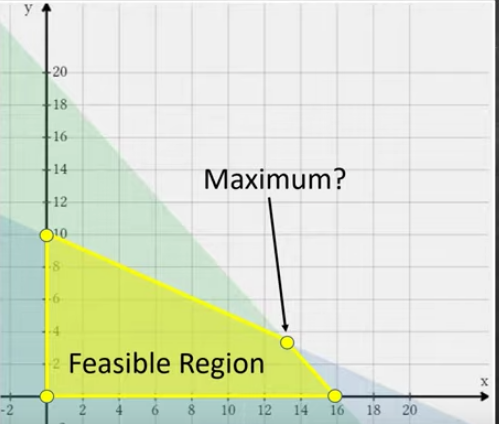

imagen extraída del ejemplo del Dr. Trefor Bazett: [https://www.youtube.com/watch?v=K7TL5NMlKIk](https://www.youtube.com/watch?v=K7TL5NMlKIk)

## Implementación del método Simplex en MatLab:

Procedemos a mostrar nuestra solución.

%Código de método simplex
%Objetivo es resolver una optimización min(J(x)=c*x) dado Ax*b
A=[2,1,1,0,0,0;     %Se Define la matriz A como la matriz que refleja los coeficientes en cada una de las variables
    1,1,0,1,0,0;    %en cada una de las restricciones
    1,2,0,0,-1,1];
b=[20;18;12];       %Se define el vector b con los valores de cada ecuación
c=[5,4,0,0,0,-5];   %Se define la función objetivo
[Z,x]=simplex_matricial(A,b,c)  %Se manda a llamar al método simplex

Z =      2
    16
     0
     0
    22
     0


x = 74


A=[3,2,1,1,0;       %Segundo ejemplo con distintas dimensiones
    2,5,3,0,1];
b=[10;15];
c=[2,3,4,0,0];
[Z,x]=simplex_matricial(A,b,c)

Z =      0
     0
     5
     5
     0


x = 20

## Funciones

function [Z,x]=simplex_matricial(A,b,c)
    validar(A,b,c); %Revisa que cada variable sea del tipo correcto para el método simplex
    %Matriz logica copia de A que es distinta de 0
    q = (A ~= 0);
    q = find(sum(q,1)==1 & sum(A,1)==1); %Columnas con solo un 1 para la primera vuelta   
    
    %Definimos matriz B
    B=A(:,q(:));
    %Calculamos Cb
    Cb=c(q(:));
    [L,U,P]=LUPS(B);
    %Hacemos el vector de renglones intercambiados a una matriz diagonal de vectores intercambiados 
    %Calculamos la fila que indica si hay negativo
    zaux=Cb*(U\L\(P*A))-c;
    %Contador para no pasarnos del limite
    i=0;
    MAX=10;
    while i<MAX && any(zaux<0)
        i=i+1;
        [~,J] = min(zaux); %encontrar el menor negativo en las columnas
        B_inv_A=U\(L\(P*A)); %Calculamos B inversa * A
        B_inv_b=U\(L\(P*b)); %Calculamos B inversa * b
        
        %Esta variable sirve para evitar los valores negativos, pues al
        %realizar la operacion deben ser infinitos, entonces cambiamos los
        %valores negativos por ceros
        
        aux=B_inv_A(:,J);
        d=find(aux<0);
        if ~isempty(d)
         aux(d(:))=0;
        end
        
        %Encontramos fila pivote
        [~,pivote] = min(B_inv_b./aux);       
        %Cambiamos el orden de las columnas con las que se esta trabajando
        %para la nueva matriz B
        q(pivote)=J;   
        %Realizamos las operaciones con B para encontrar si hay nuevos
        %valores negativos que se tengan que cambiar
        B=A(1:end,q(:));
        [L,U,P]=LUPS(B);
        Cb=c(q(:));
        %Actualizamos la nueva fila
        zaux=Cb*(U\L\(P*A))-c;
    end
    %Calculamos el valor optimizado
    %Calculamos el vector Z resultante
    [~,col]=size(A);
    Z=zeros(col,1);
    B_inv_b=U\(L\(P*b));
    x=Cb*B_inv_b;
    for j=1:length(B_inv_b)
        Z(q(j))=B_inv_b(j);
    end
end


function validar(A,b,c)
    if ~ismatrix(A), error('A debe ser matriz'), end
    if ~isvector(b), error('b debe ser vector'), end
    if ~isvector(c), error('c debe ser vectorr'), end
    [m,n]=size(A);
    if length(b) ~= m, error('b debe tener el mismo tamaño que las filas de A'), end
    if length(c) ~= n, error('c debe tener el mismo tamaño que las columnas de A'), end
end

function [L,U,P,s] = LUPS(A)   %La función LUPS tomará una función cuadrada A y se obtendrá su factorizción LU
                               %tomando como parámetros la matriz de
                               %permutación P y el número de intercambio de
                               %renglones s
    [m,n]=size(A);
    if m~=n
        error('A debe ser cuadrada') %se corrobora el tamaño de la matriz
    end
    
    U=A;
    L=eye(n);
    P=eye(n);
    s=0;
    
    for i=1:n
        [vm,r]=max(abs(U(i:n,i)));
        if vm==0
            error('A es singular')
        end
        
        iMay=r+i-1;
        if iMay~=i
            U([i,iMay],:)=U([iMay,i],:);
            P([i,iMay],:)=P([iMay,i],:);
            s=s+1;
        end
        
        for j=i+1:m
            mult=U(j,i)/vm;
            L(j,i)=mult;
            cols=i:n;
            U(j,cols)=U(j,cols)-mult*U(i,cols);
        end
    end

end


## Conclusiones:

    El método simplex es uno de los algoritmos más utilizados y eficientes que se han inventado, e inclusive hasta hoy en día es el método estándar utilizado por las computadoras para solucionar problemas de optimización. Particularmente en los últimos años con el aumento exponencial de información recopilada en prácticamente todos los campos (a través de dispositivos interconectados y ampliamente usados como los celulares) es posible crear modelos matemáticos con una enorme cantidad de restricciones y funciones a optimizar, donde el método simplex es una herramienta crucial para encontar de manera eficaz una solución óptima. Un ejemplo de esto podrían ser los algoritmos de las redes sociales que buscan optimizar el contenido brindado al usuario para maximizar el tiempo que estará conectado. (¡No siempre se usa el método simplex para el bien!)

## Referencias:

[1] [https://www.britannica.com/topic/simplex-method](https://www.britannica.com/topic/simplex-method)

## Fuentes:

[https://www.ingenieriaindustrialonline.com/investigacion-de-operaciones/metodo-simplex/](https://www.ingenieriaindustrialonline.com/investigacion-de-operaciones/metodo-simplex/)

[https://www.youtube.com/watch?v=FY97HLnstVw](https://www.youtube.com/watch?v=FY97HLnstVw)

[https://www.youtube.com/watch?v=K7TL5NMlKIk&t=610s](https://www.youtube.com/watch?v=K7TL5NMlKIk&t=610s)